# Lecture 8 Optical Ranging - Passive

## 1. Introduction

### 1.1 3D volumetric imaging vs 3D surface imaging (ranging)

An important distinction should be made between 3D volumetric imaging systems and 3D surface imaging before our discussion on ranging. The data acquired by 3D volumetric imaging systems are 3D arrays, such as tomographic imaging (ILL. 1.1 Top). 3D surface imaging system is essntially a ranging systems, which measures the depth for every pixel on a 2D imager. The former are commonly used in medical imaging such as computed tomography (CT), whereas the latter, often collectively referred to as light detecction and ranging (LiDAR), are currently of great interest primarily driven by its applications in autonomous systems. In Lectures 8 and 9, we will focus on the passive and active optical ranging methods, respectively.

Optical coherence tomography (OCT) is a coherent volumetric 3D imaging technique in visible and near infrared (NIR) wavelength, which will be discussed in Lecture 10. CT is one of the most common medical diagnosis imaging modality in the x-ray regime, which will be discussed in Lecture 12.

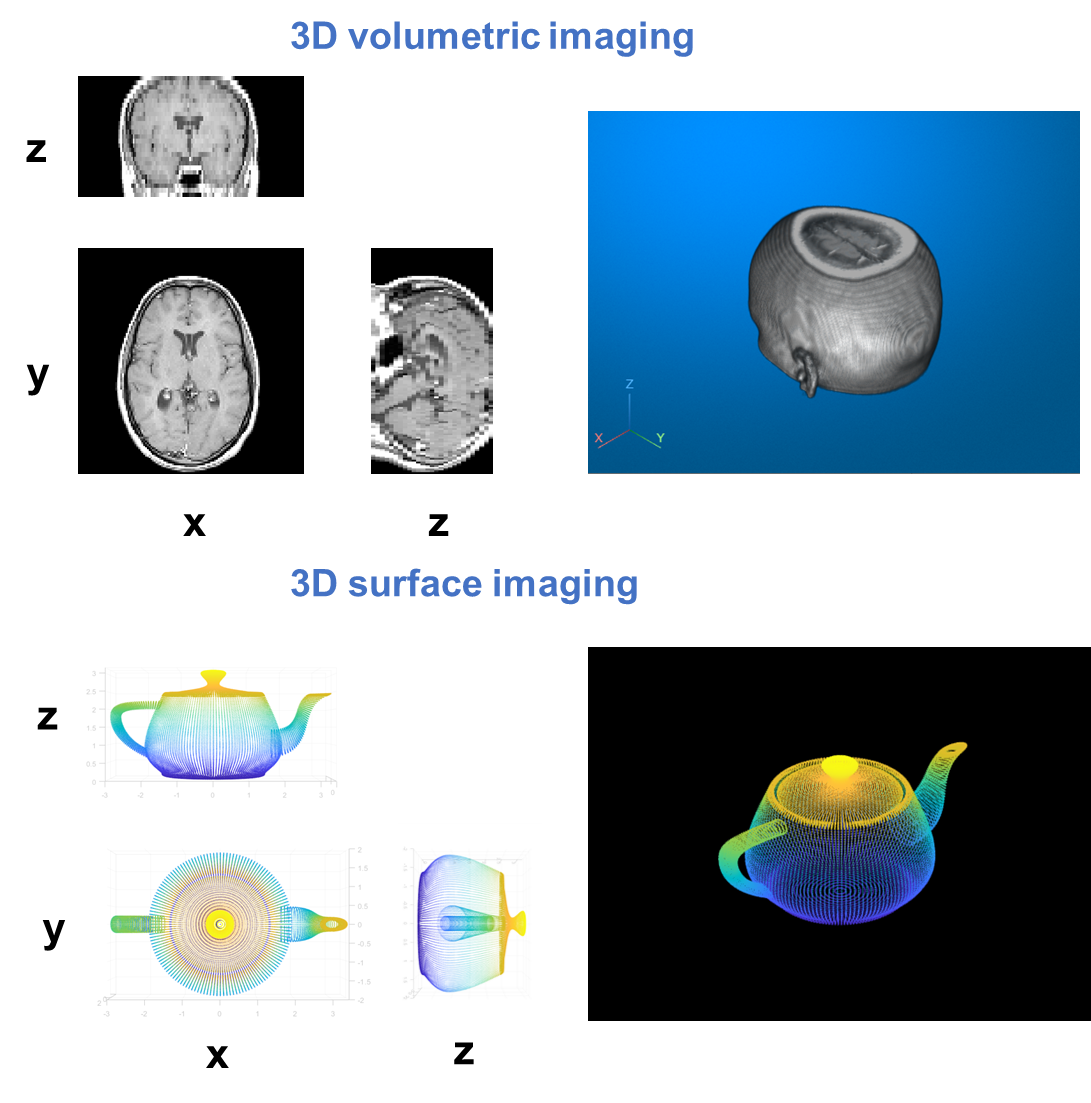

**ILL. 1.1 ***3D volumetric imaging vs. 3D surface imaging*

### **1.2 Point cloud: 3D ranging data storage**

The point cloud data files are categorized according to the spatial relationships between the points. The storage layout of an **organized point cloud** relates to the spatial layout represented by the xyz-coordinates of its points. In contrast, **unorganized point clouds** consist of a single stream of 3-D coordinates, each coordinate representing a single point. You can also differentiate these point clouds based on the shape of their data. Organized point clouds are MxNx3 arrays, with the three channels representing the x, y, and z coordinates of the points on a M by N imager pixels. Unorganized point clouds are Mx3 matrices, where M is the total number of points in the point cloud.

***Example 1.1 ***

PLY data format is a common format for store unorganized point cloud data. Here we explain the .ply data format and display first 19-20 lines of the data.

**(a) **Teapot example

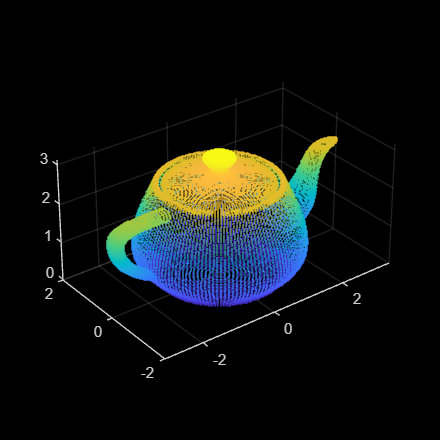

% PLY point cloud file
ptCloud = pcread('teapot.ply');
figure;
pcshow(ptCloud); % display the point cloud*
set(gcf,'Position', [100 100 400 400])

pcwrite(ptCloud,"teapotOut",PLYFormat="ascii"); % save point cloud 
% show the raw ply file
ptcID = fopen('teapotOut.ply');
plyTxt = textscan(ptcID, '%s', 'Delimiter','\n');
for ii = 1: 20 % display the first 20 lines of the raw files*
    jj = ([num2str(ii), '. ']);
    num_list = ([jj,plyTxt{1}{ii}]);
    disp(num_list)
end 

1. ply
2. format ascii 1.0
3. element vertex 41472
4. property float x
5. property float y
6. property float z
7. end_header
8. 0.000000 -1.500000 2.400000
9. 0.000000 -1.494556 2.410928
10. 0.000000 -1.488956 2.421214
11. 0.000000 -1.483228 2.430857
12. 0.000000 -1.477401 2.439857
13. 0.000000 -1.471501 2.448214
14. 0.000000 -1.465559 2.455929
15. 0.000000 -1.459600 2.463000
16. 0.000000 -1.453654 2.469429
17. 0.000000 -1.447747 2.475214
18. 0.000000 -1.441910 2.480357
19. 0.000000 -1.436168 2.484857
20. 0.000000 -1.430550 2.488714


*Teapot PLY data: 

- Line 2 defines the file format (ASCII or binary).

- Lines 3-6 define the element type, number of elements, and data format.

- Line 7 is the end of the header.

- Lines 8-20 show the unorganized point cloud data in (x,y,z) coordinates.

**(b) **Corner example

%% display PLY with surface
%select between corner.ply and corner2.ply, corner2.ply contains the
%surfaces
file_name = 'corner.ply';
fileID = fopen(file_name);
plyTxt = textscan(fileID, '%s', 'Delimiter','\n');
for ii = 1: length(plyTxt{1})
    jj = ([num2str(ii),'. ']);
    num_list = ([jj,plyTxt{1}{ii}]);
    disp(num_list);
end

1. ply
2. format ascii 1.0
3. element vertex 4
4. property float x
5. property float y
6. property float z
7. property uchar red                  
8. property uchar green
9. property uchar blue
10. element face 4
11. property list uchar int vertex_index  
12. end_header
13. 0 0 0 255 255 255                       
14. 0 0 1 255 0 0
15. 0 1 0 0 255 0
16. 1 0 0 0 0 255
17. 3 0 1 2                          
18. 3 0 2 3 
19. 3 0 3 1
20. 3 1 2 3


*Corner PLY data: 

- Line 2 defines the file format (ASCII or binary).

- Lines 3-9 shows the vertex location and color defined in RGB.

- Lines 10-11 and 17 onward show the surfaces that contain the vertex index.

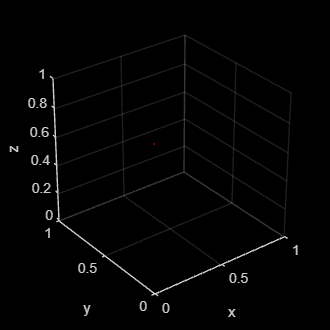

ptc_corner = pcread(file_name); % the point is very small and hard to find*
figure; % show the points
pcshow(ptc_corner);
set(gcf,'Position', [100 100 300 300])
xlabel('x')
ylabel('y')
zlabel('z')

*As described in the .ply data, the points can be found at the following locations: white (0,0,0), red (0,0,1), green (0,1,0), and blue (1,0,0). Can you tell why the mesh rendering of 'corner1.ply' and 'corner2.ply' are different?

% show mesh for 'corner2.ply'
mesh = readSurfaceMesh(file_name);
surfaceMeshShow(mesh); 
% Note that this figure opens in a separate window

### 1.3 Passive vs active ranging

**Passive imaging:**

Passive imaging relies on naturally occurring light emitted or reflected by objects in the scene without actively changing the illumination. Passive imaging is commonly used in everyday photography The following passive imaging systems are commonly used for ranging purposes.

- Stereo vision

- Light field camera and array camera

**Active imaging:** 

Active imaging involves actively illuminating the scene with a controllable source of light and measuring the reflected or scattered light to form an image. This approach allows for greater control over the imaging process but also expose the sensing source. Examples of active imaging systems for ranging include:

- Structured light

- Time of flight (TOF) locked-in imager

- Light detection and ranging (LiDAR)

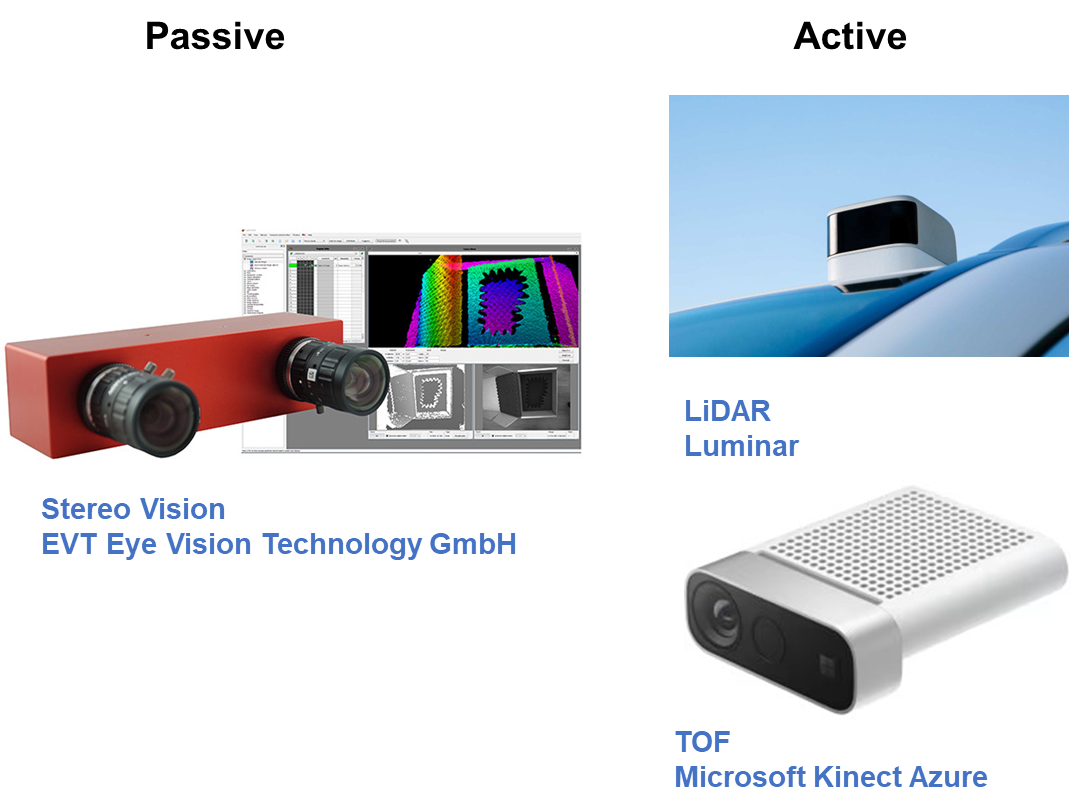

**ILL. 1.2 ***Examples of active and passive ranging systems*

## 2. Passive ranging

### 2.1 Stereo vision

Stereo vision, also known as binocular vision, is the ability to infer depth information by combining the images from 2 sperated cameras. The human visual system with two eyes, is our natural stereo vision system.

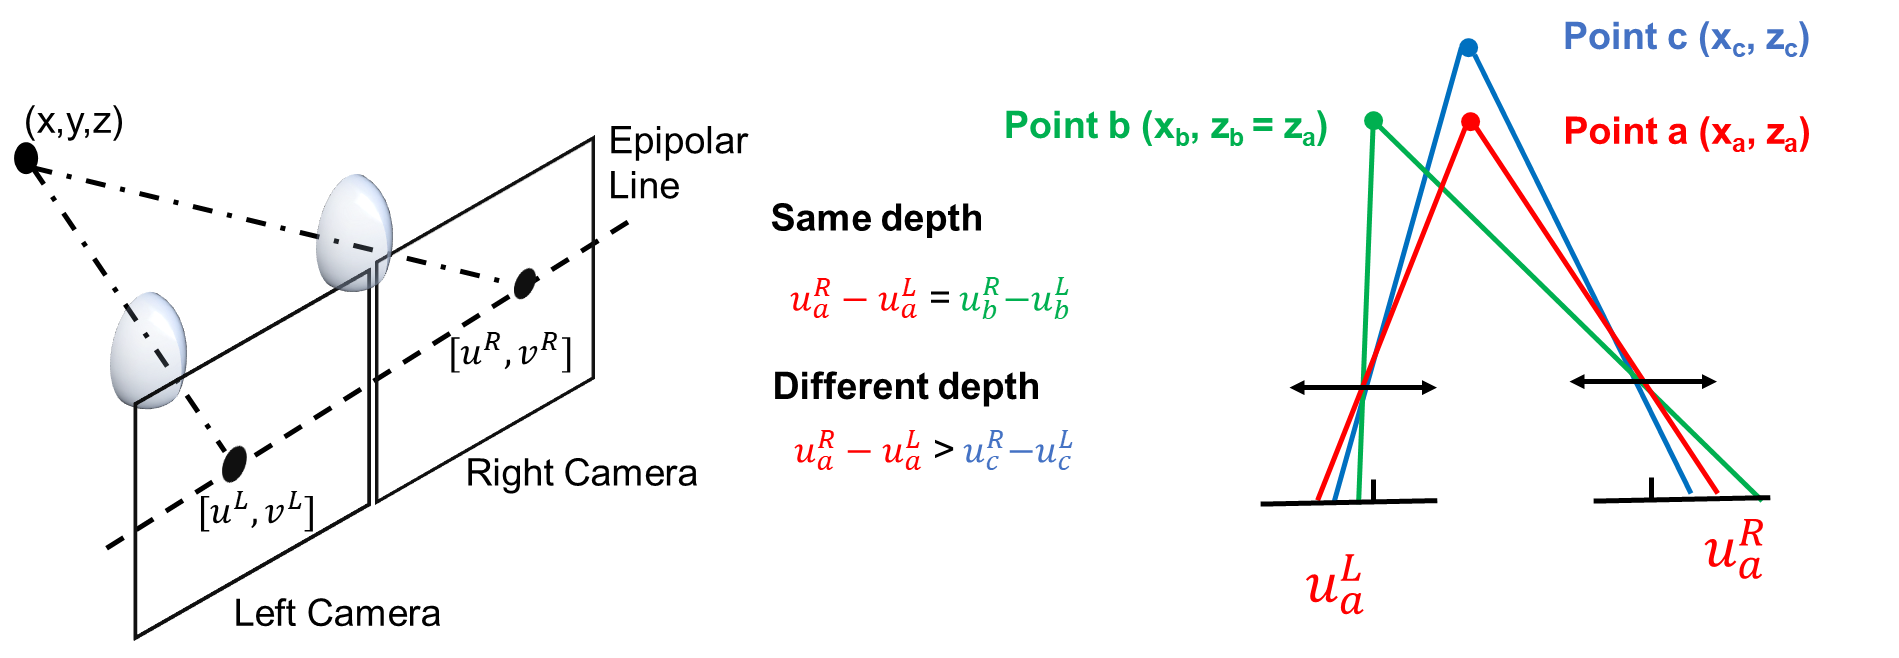

**ILL. 2.1 ***Principle of ranging based on stereo vision: the disparity (*$u^R -u^L$*) reflects the scene depth*

#### **2.1.1 Projective geometry**

The stereo vision model uses the pin-hole model, where the 3D scene is projected onto the 2D sensor as if the rays go through a pinhole in front of the sensor. The sensor is placed at the focal plane of the lens and the imaginary pinhole is located at the principal point (H').

For a single camera, the object coordinates origin is the principal point and the $z$ axis is defined as the normal direction of the imager. As shown in the figure, the point A $\left(x,y,z\right)$ in the object space is projected to a point $\left(u,v\right)$ on the imager. If the imager's origin point (O) is the intersection of the optical axis and the imager, then we can see that for a given $\left(u,v\right)$, any point along that line $\left(\frac{u}{f},\frac{v}{f},1\right)z$, will be project to $\left(u,v\right)$ on the imager. Any two points on the line only differ by a scaling constant. So to see if two points $\left(x_1 ,y_1 ,z_1 \right)$ and $\left(x_2 ,y_2 ,z_2 \right)$ will project to the same image point we only need to compare the $z$ normalized 2D coordinates $\left(\frac{x_1 }{z_1 },\frac{y_1 }{z_1 },1\right)$and $\left(\frac{x_2 }{z_2 },\frac{y_2 }{z_2 },1\right)$. Therefore it is convenient to define **homogeneous coordinates**. In homougeneous coordinates, two vectors are the same as long as the normalized 2D coordinates (wrt. the 3rd coordinate) are the same. For example,


$$\left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
u/w\\
v/w\\
1
\end{array}\right\rbrack$$


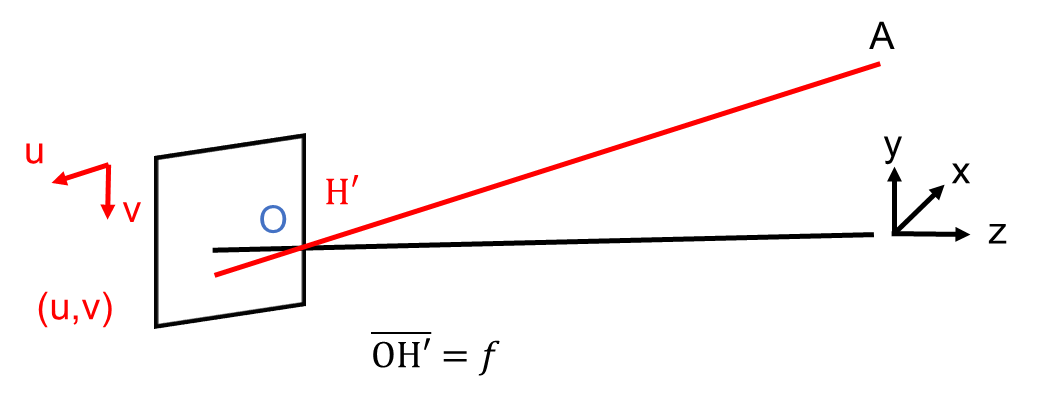

**ILL. 2.2 ***Single camera projective geometry.  Point A with global coordinates *$\left(x,y,z\right)$* in the object space is projected to a point *$\left(u,v\right)$* on the imager*

On the imaging plane, the homogeneous coordinates are 


$$\left(u,v,1\right)$$


In object space, the homogeneous coordinates are


$$\left(x,y,z,1\right)$$


The projection process from the object space $\left(x,y,z,1\right)$ to the image plane $\left(u^{\prime } ,v^{\prime } ,w^{\prime } \right)$ can be expressed as:

  $\left\lbrack \begin{array}{c}
u^{\prime } \\
v^{\prime } \\
w^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
f & 0 & 0 & 0\\
0 & f & 0 & 0\\
0 & 0 & 1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{fx}\\
\textrm{fy}\\
z
\end{array}\right\rbrack$, Eq (1)

Converting from homogeneous coordinates to imager coordinates: 


$$\left\lbrack u^{\prime } ,v^{\prime } ,w^{\prime } \right\rbrack \longrightarrow \left\lbrack u,v\right\rbrack =\left\lbrack \frac{u^{\prime } }{w^{\prime } },\frac{v^{\prime } }{w^{\prime } }\right\rbrack =\left\lbrack \frac{f}{z}x,\frac{f}{z}y\right\rbrack$$


If the intersection of the optical axis and the sensor is not coincident with the origin of the imager, but at $\left(u_0 ,v_0 \right)$, then the matrix in Eq (1) can be expressed as:


$$\left\lbrack \begin{array}{cccc}
f & 0 & u_0  & 0\\
0 & f & v_0  & 0\\
0 & 0 & 1 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
f & 0 & u_0 \\
0 & f & v_0 \\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0
\end{array}\right\rbrack =\mathbf{K}\left\lbrack {\mathbf{I}}_{3\textrm{x3}} |{\mathbf{O}}_{3\textrm{x1}} \right\rbrack$$


$\mathbf{K}$ is called the calibration matrix.

#### 2.1.2 Stereo camera in parallel geometry

For two parallel, identical cameras facing the $z$ direction with an offset of $b$ in the $x$ direction.


$${\mathbf{K}}_1 ={\mathbf{K}}_2 =\left\lbrack \begin{array}{ccc}
f & 0 & 0\\
0 & f & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


Shifts of camera principal points are ${\mathit{\mathbf{s}}}_1 =\left\lbrack -\frac{b}{2},0,0\right\rbrack$ and ${\mathit{\mathbf{s}}}_2 =\left\lbrack \frac{b}{2},0,0\right\rbrack$.

For camera 1


$${\mathit{\mathbf{w}}}_1 ={\mathbf{K}}_1 {\mathbf{I}}_{3\textrm{x4}} \left(\mathbf{r}-{\mathbf{s}}_1 \right)$$



$$\frac{u_1 }{f}=\frac{x+b/2}{z},\;\frac{v_1 }{f}=\frac{y}{z}$$


For camera 2, simply change the subscripts to 2. The $v$ coordinate is the same (the parallel line $v=\textrm{const}$, called the epipolar line). The disparity $d$ is the shift of the corresponding point on the epipolar line.


$$d=u_1 -u_2 =\frac{b}{z}f$$


The triangulated depth $z$ is


$$z=\frac{b}{d}f$$


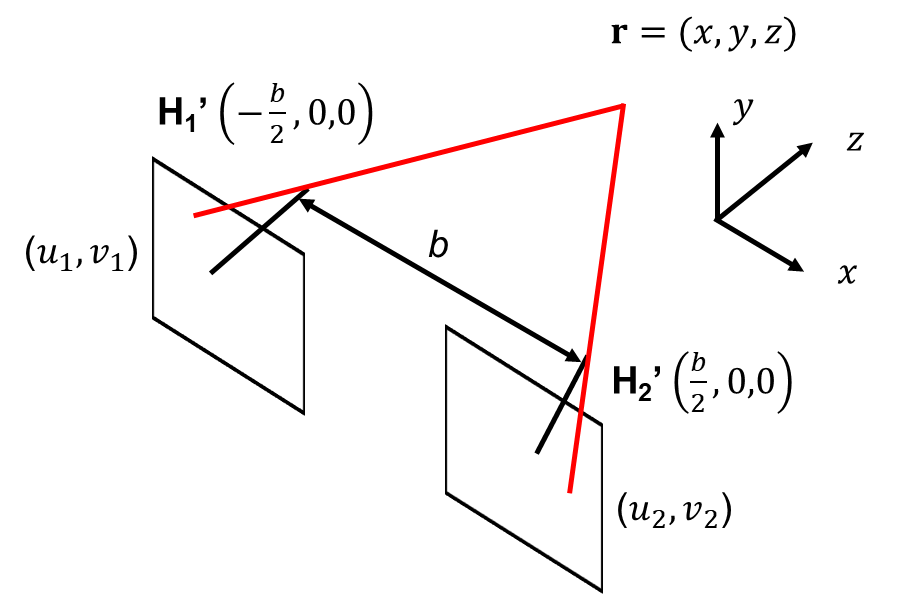

**ILL. 2.3 ***Stereo Camera in parallel geometry for Example 2.1*

***Example 2.1 ***

Stereo projection in parallel geometry

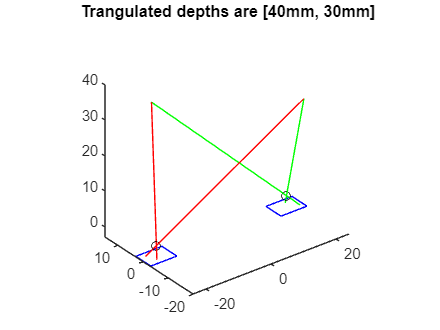

% geometric projection to stereo camera
u_range = 8; % [unit: mm]
v_range = 6; % [unit: mm]
f = 3; % focal length [unit: mm]
% camera 1 
x1_0 = -20; % [unit: mm]
y1_0 = 0; % [unit: mm]
u1_max = x1_0+u_range/2;
u1_min = x1_0-u_range/2;
v1_max = y1_0+v_range/2;
v1_min = y1_0-v_range/2;

% camera 2
x2_0 = 20; % [unit: mm]
y2_0 = 0; % [unit: mm]
u2_max = x2_0+u_range/2;
u2_min = x2_0-u_range/2;
v2_max = y2_0+v_range/2;
v2_min = y2_0-v_range/2;

% object location
x = [10,-10];
y = [-20,15];
z1 = 40;
z = [z1,30]; 
r1 = [x-x1_0;y-y1_0;z;ones(1,2)]; % object homogenous coordiante for camera 1 
r2 = [x-x2_0;y-y2_0;z;ones(1,2)]; % object homogenous coordiante for camera 2

K1 = [-f, 0, 0, 0;
      0, -f, 0, 0;
      0, 0, 1, 0];
K2 = [-f, 0, 0, 0;
      0, -f, 0, 0;
      0, 0, 1, 0];
w1 = K1*r1;
u1 = w1(1,:)./w1(3,:);
v1 = w1(2,:)./w1(3,:);
w2 = K2*r2;
u2 = w2(1,:)./w2(3,:);
v2 = w2(2,:)./w2(3,:);

%% triangulation to estimate the depth
z_tr = f.*(x1_0-x2_0)./(u1-u2); % put the triangulation results

% plot cameras
figure()
stereo_proj(u1_min, u1_max, v1_min, v1_max, f, u2_min, u2_max, v2_min, ...
    v2_max,x1_0, x2_0, y1_0,y2_0, x, y, v1, v2, z, u1, u2);

title(['Trangulated depths are [', num2str(z_tr(1)), ...
    'mm, ',num2str(z_tr(2)),'mm]']);
set(gcf,'Position', [100 100 400 300])

*Notes:*

- *The source code for stereo_proj is attached in the **Appendix*

#### 2.1.3 Epipolar geometry

In our example, you probably have noticed that the $v$ coordinated of the left and right imagers are the same. This parallel line has another name: **epipolar line***, *which is the projection image of the ray through the principle points. The **epipole**, is the point of intersection of the line joining the camera centers with the image plane. In parallel geometry, the camera center is parallel to the camera plane, so the epipole is at infinity and the left and right epipolar lines are parallel to each other. 

The importance of defining the epipolar line is that to search the corresponding points for two cameras, we do not need to search the whole 2D plane on the other imager, but only the point on the corresponding epipolar line.

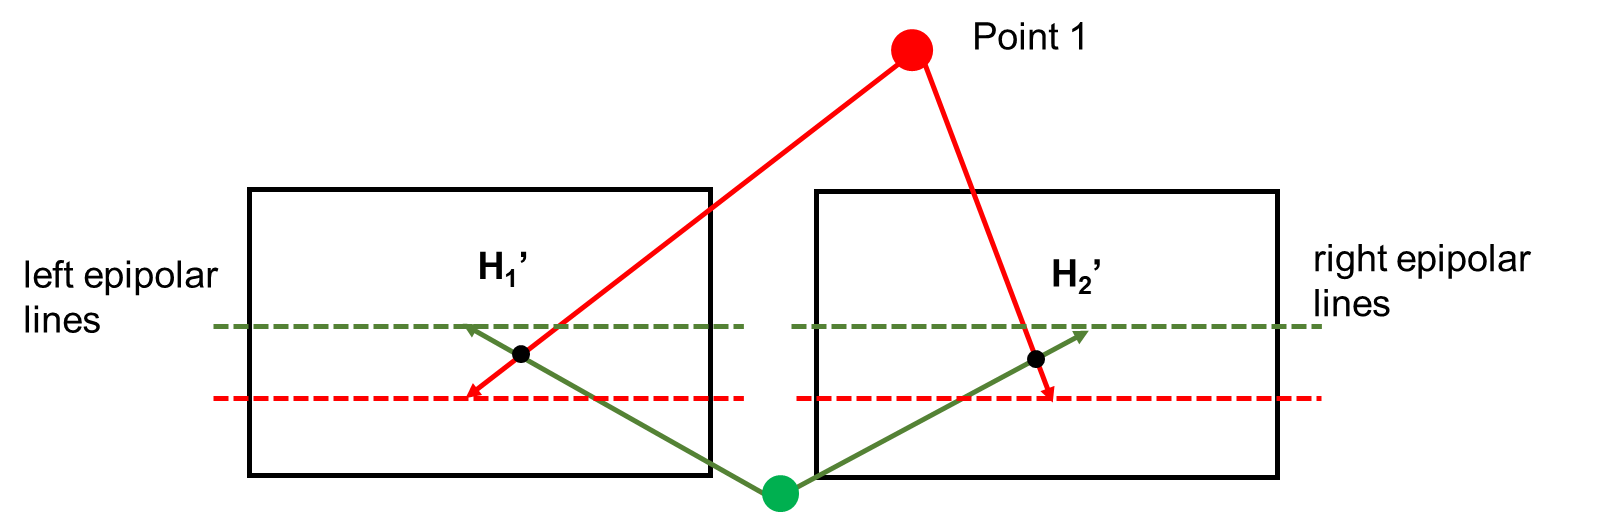

**ILL. 2.4 ***Parallel epipolar lines for parallel geometry*

#### **2.1.4 Practical considerations**

In *Example 2.1*, the two cameras are in parallel geometry with principle points coordinates calibrated. In addition, the projected points correspondence (i.e. two points corresponding to the same point in object space) are also known. However, in practice, this information is usually unknown and need more steps before the triangulation calculation. Prior to range estimation, the following steps are needed:

- Camera calibration: the rotation, magnification, even the distortion of each camera need to be carefully calibrated

- Rectification of the collected images

- Stereo correspondence algorithms

- Depth estimation (Triangulation)

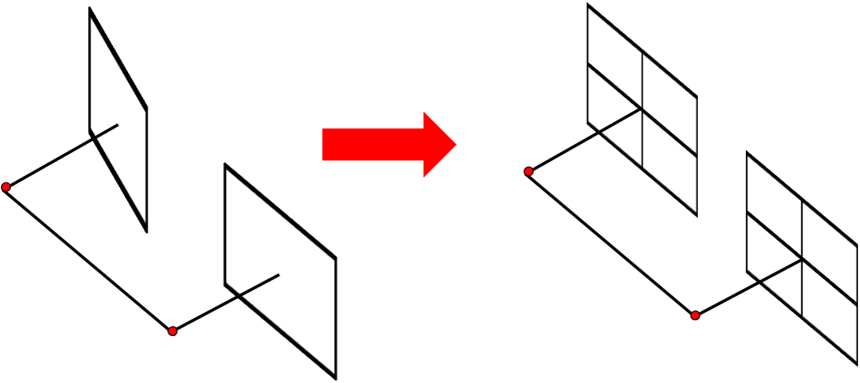

**ILL. 2.5 ***Rectification: convert converging cameras to parallel camera geometry*

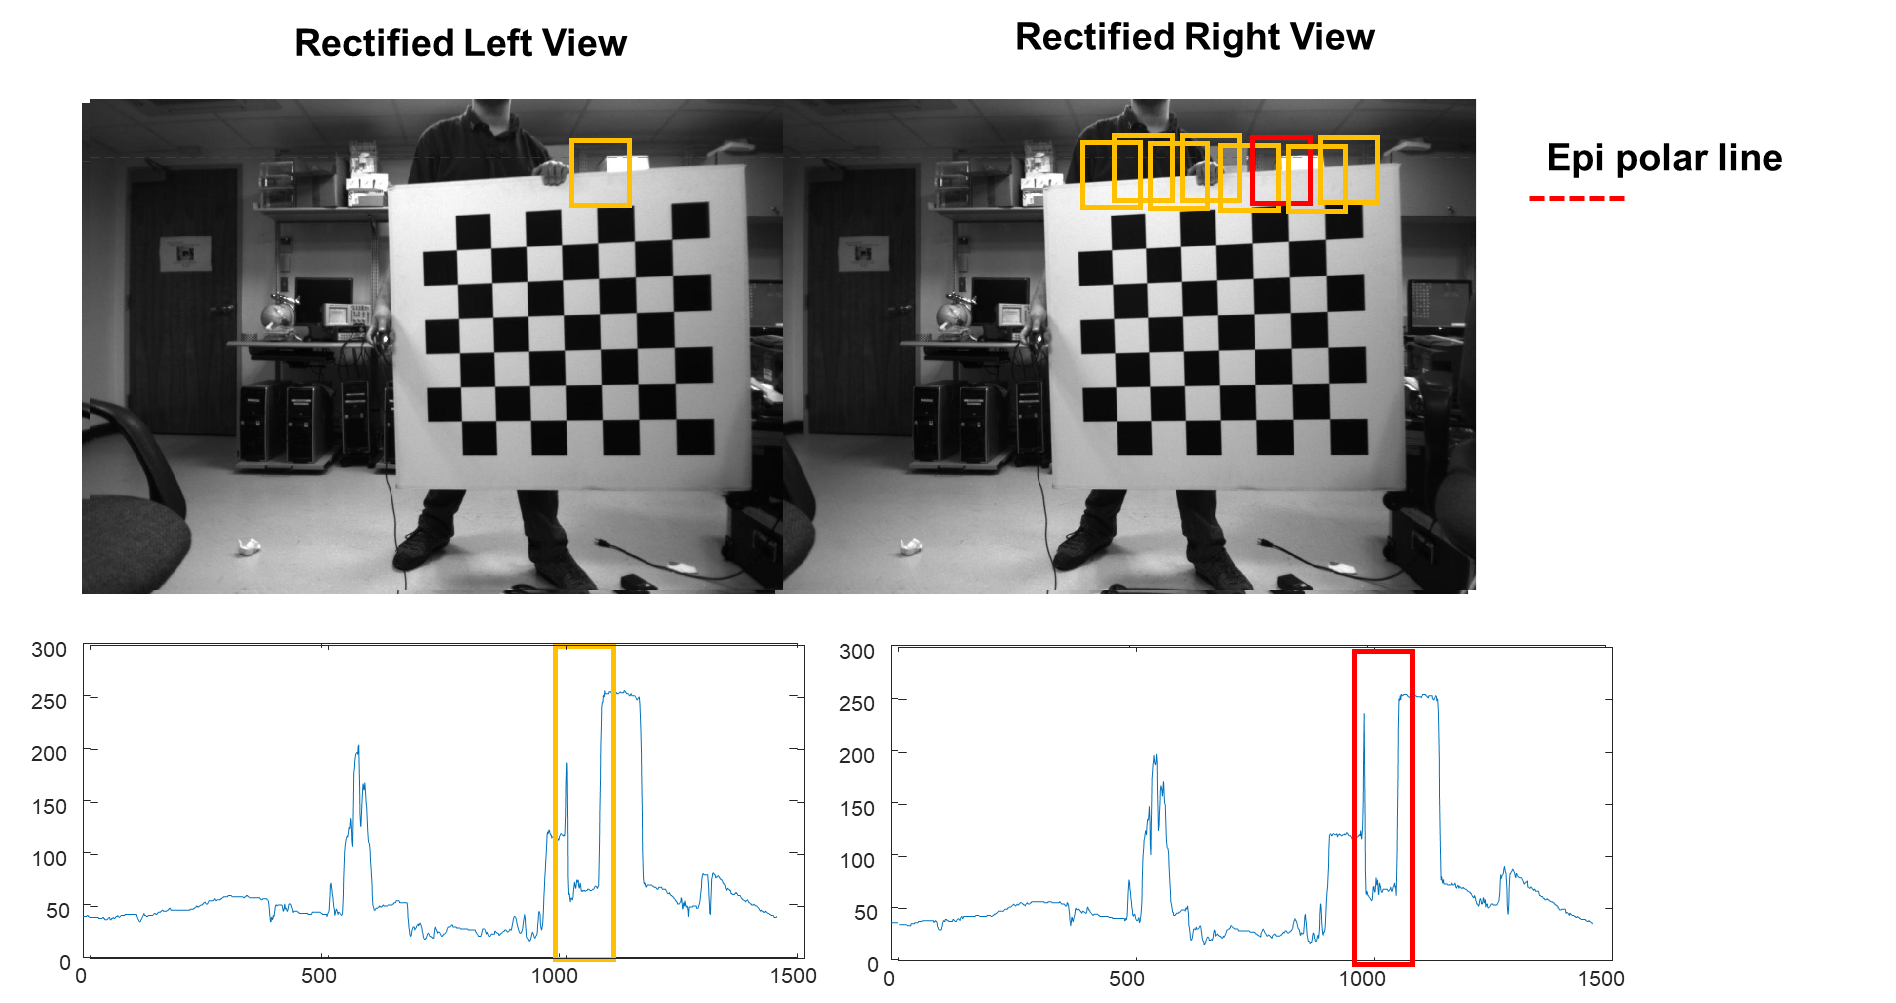

**ILL. 2.6 ***Stereo correspondence algorithms: searching corresponding points along the epipolar line*

### 2.2 Light field camera

A light field camera is a type of camera that captures not only the intensity and color of the scene but also the incident directions of the light rays. Under geometrical optics assumption, traditional cameras capture a two-dimensional 'projection' of the scene, while light field cameras capture addditional information about the incoming light rays, allowing for various post-acquisition manipulations and enhancements, including performing aperture adjustments and focusing through post processing. This allows the photographers and filmmakers to adjust depth, focus, and perspective in ways that were not possible with tradtional cameras. Light field cameras have applications in AR/VR, 3D imaging, and cinematography.

One common approach to capture the angular information of the incident ray by using an array of micro lenses placed in front of the camera sensor. These micro lenses help capture light rays from different angles and record the directionality of the light.

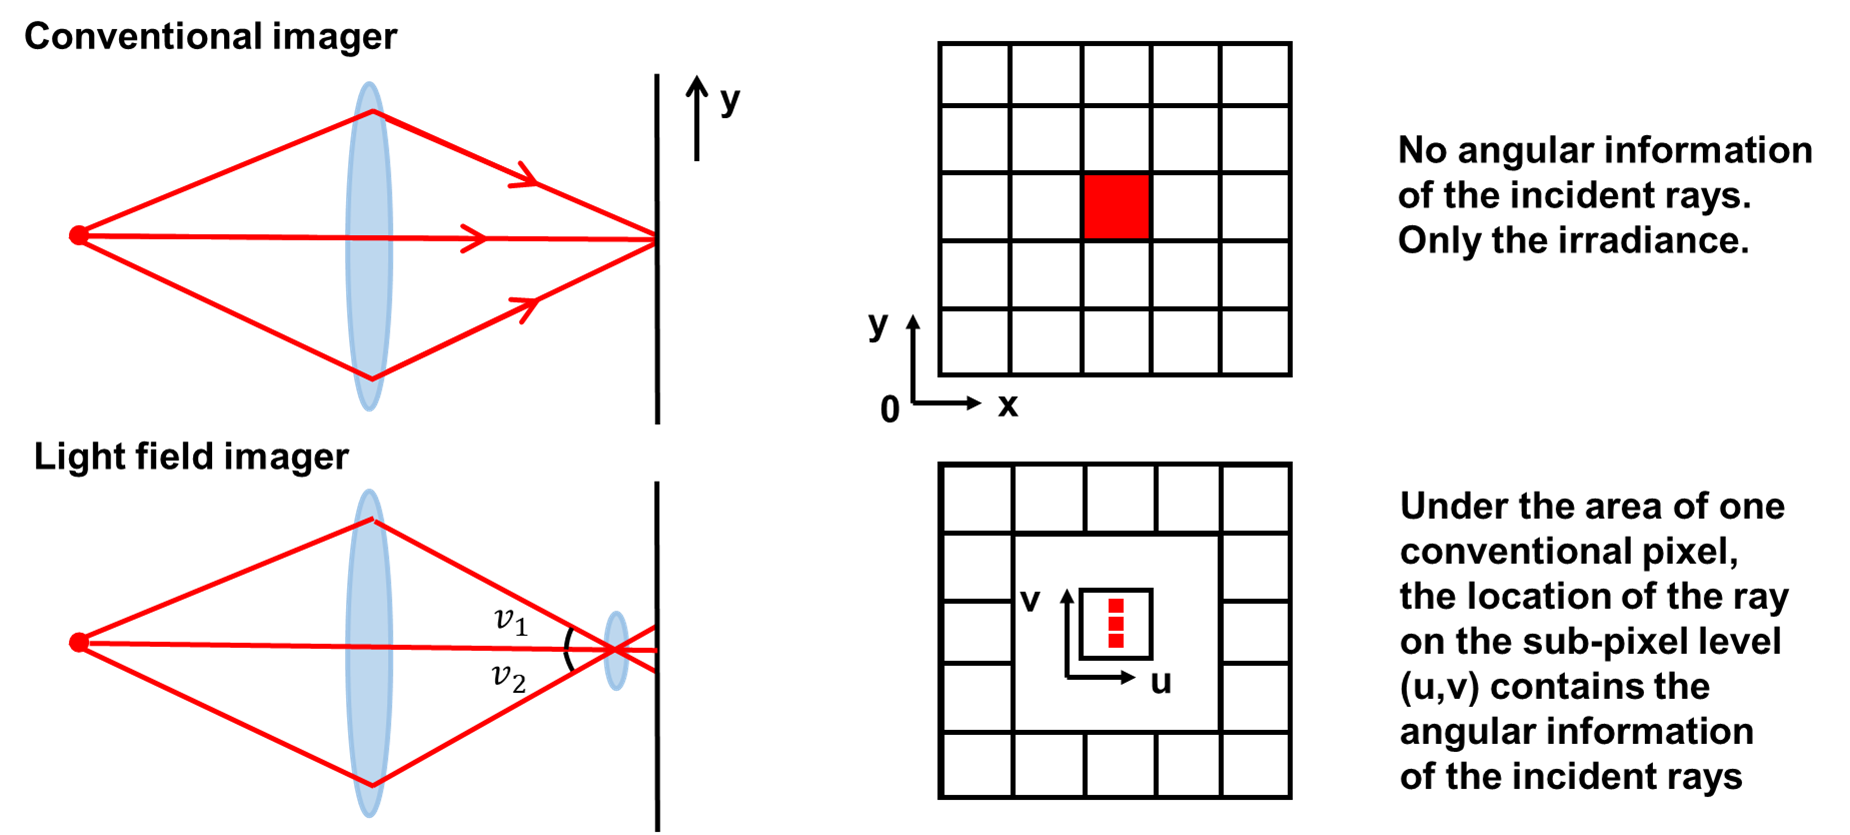

**ILL. 2.7 ***Light field sensor based on microlens array*

#### **2.2.1 4D Light field data format**

For the light field camera that uses a microlens array to collect the angular information, a large format focal plane array (FPA) records both the spatial and angular data.

- The spatial coordinate sampling rate and size is determined by the dimension and the number of lenses of the microlens array, respectively.

- Under each microlens, the pixels record the angular distribution.

For example, if we have an FPA with raw pixel format to be 4000 by 4000 and each micro lens occupies 16 by 16 FPA pixels, then the spatial coordinate $\left(x,y\right)$ size is 250 by 250, and the angular coordinate size $\left(u,v\right)$ is 16 by 16. Organize the data to a 4D dataset with $\left\lbrack u,v,x,y\right\rbrack$ coordinates, and the size of the 4D tensor is [16,16,250,250]. By fixing u and v, we can observe the scene from a given perspective, illustrated in ILL. 2.8

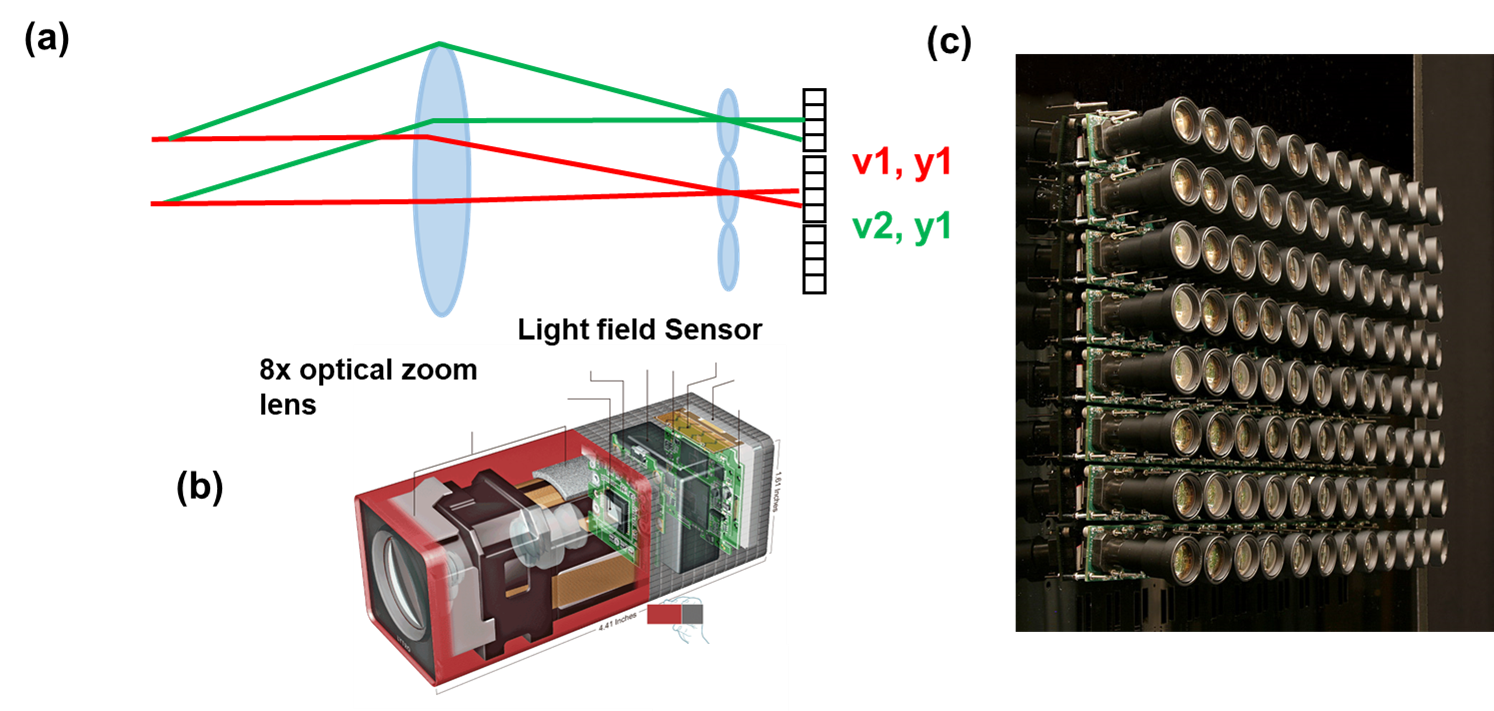

**ILL. 2.8 ***(a) Fixing the angular coordinates *$\left(u,v\right)$*, is equivalent to fixing a perspective. (b) Lytro camera, based on lenslet light field sensor (source: *[*https://archive.nytimes.com/www.nytimes.com/interactive/2012/03/01/business/inside-the-lytro.html*](https://archive.nytimes.com/www.nytimes.com/interactive/2012/03/01/business/inside-the-lytro.html)*). (c) Alternative implementation using camera array shown in the right figure (source: *[*http://graphics.stanford.edu/projects/array/)*](http://graphics.stanford.edu/projects/array/))

#### **2.1.2 Focal stack reconstruction**

To simplify the discussion, lets only look at two perspective $v_1$ and $v_2$. If the object is in focus, as shown in ILL. 2.9 Top, the two perspectives wil land in the region corresponding to the same spatial coordinates. However, when the defocus $\Delta z$ is introduced in the object space, the non-zero perspective $v_2$ will have a shift in spatial coordinates. Using simple geometric optics, 


$$\Delta y=y_2 -y_1 =v_2 \times \Delta z^{\prime } =\frac{f^2 v_2 }{{\left(z-f\right)}^2 }\Delta z$$


Where $z$ is the in-focus object plane depth, $f$ is the focal length, $\Delta z$ and$\Delta z^{\prime }$ are the defocus in the object and image space, respectively. $v_2$ is the perspective angle. This means that if we shifting the 4D light field data, we can select the focus plane. For example, if we combine$v_2$ pixel on $y_2$ tile  with $v_1$ pixel on $y_1$ tile, we can shift the focus in object plane by $\Delta z$.

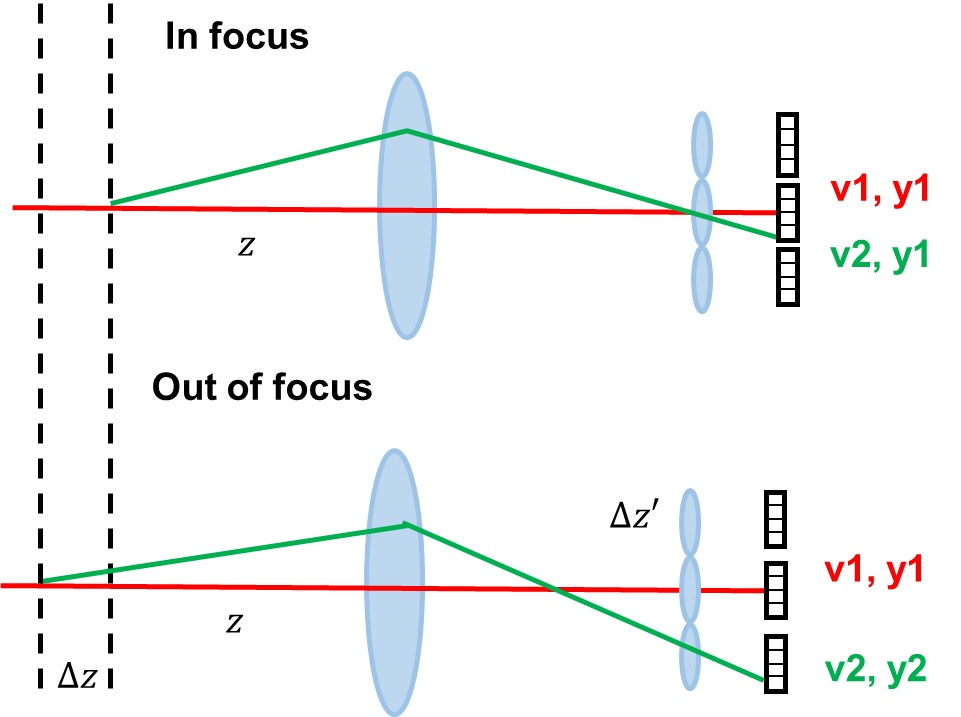

**ILL. 2.9 ***Defocusing leads to spatial coordinate shift*

***Example 2.2 ***

Converting 4D light field data to focal stack.

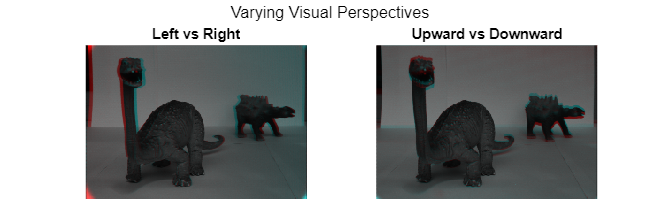

% load the image file 
load dinosaur.mat
[nu,nv,nx,ny]=size(LF_lr);

cu = round((nu+1)/2); % center angular pixel horizontal
cv = round((nv+1)/2); % center angular pixel vertical
light_field = single(LF_lr); % convert to single precision

figure;
subplot(121) % show the left perspective vs right perspective
sgtitle('Varying Visual Perspectives')
I_left = squeeze(LF_lr(cu,2,:,:));
I_right = squeeze(LF_lr(cu,nv-2,:,:));
imshow(stereoAnaglyph(I_left,I_right))
title('Left vs Right')
subplot(122) % show the upper perspective vs lower perspective
I_up = squeeze(LF_lr(2,cv,:,:));
I_down = squeeze(LF_lr(nv-2,cv,:,:));
imshow(stereoAnaglyph(I_up,I_down))
title('Upward vs Downward')
set(gcf,'Position', [100 100 600 200])

% generate focal stack
max_shift = 1*cv; % 1 pixels in y dimension.
depth = -max_shift:max_shift; % set the focal shift range.
nz = length(depth);
focal_stack = zeros([nx,ny,nz]);

for kk = 1:nz
    for ii = 1:nu
        for jj = 1:nv
            focal_stack(:,:,kk) = focal_stack(:,:,kk) + ...
                imtranslate(squeeze(light_field(ii,jj,:,:)),...
                [round((jj-cv)*depth(kk)/cv),round((ii-cu)*depth(kk)/cu)]);
        end
    end
end

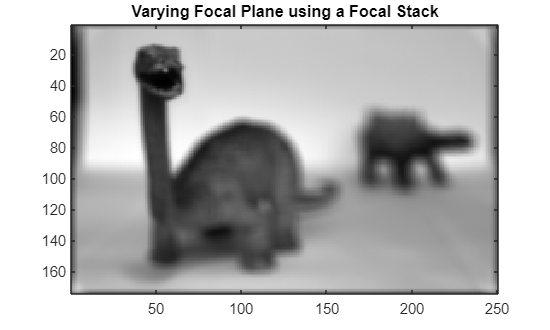

idx_z = 13; %Modify focus using this slider
figure;
imagesc(squeeze(focal_stack(:,:,idx_z)));
title('Varying Focal Plane using a Focal Stack')
colormap('gray')
set(gcf,'Position', [100 100 500 300])

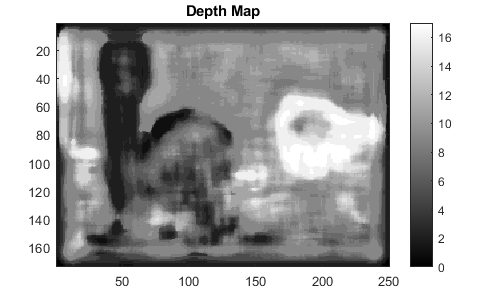

%% Depth estimation
dr = 8; % blur disk radius
H = fspecial('disk',dr);
V = zeros(size(focal_stack));
I = max(focal_stack(:));
for kk=1:nz
    frame = squeeze(focal_stack(:,:,kk))./max(focal_stack(:,:,kk),[],"all");
    V(:,:,kk)=(imfilter(frame,H)-frame).^2;
end

[~,idx]=min(V,[],3);

m = 15; % median filter box size
depth_map=medfilt2(idx,[m,m]);

figure()
imagesc(depth_map);
title('Depth Map')
colormap('gray')
colorbar
set(gcf,'Position', [100 100 500 300])

*Example 2.2* shows a 4D light field data file saved in dinosaur.mat, which is a low resolution version from the EPFL light-field dataset [http://plenodb.jpeg.org/lf/epfl/.](http://plenodb.jpeg.org/lf/epfl) The 4D light field data here does not use specific physical parameters (focal length of the lanscape lens, $f$, and the microlens, $f_m$, number of pixels for angular coordinates $N_v$, and the object in-focus depth $z$), it only shows the concept focal stack reconstruction. If all the parameters are given, the focal stack depth distance $\delta z$ between two stacks can be calculated as:


$$\delta z=\frac{{\left(z-f\right)}^2 }{f^2 }N_v {\;f}_m$$


From the focal stack, there are various algorithms to estimate the depth. Here we listed a simple algorithm that uses a linear filter on all focal depth. The frame within the stack with the greatest intensity variance drop is considered the in-focus plane. However, direct depth information from 4D light field date yields superior depth estimation. For more details, please refer to:

H. -G. Jeon *et al*., "Accurate depth map estimation from a lenslet light field camera," *2015 IEEE Conference on Computer Vision and Pattern Recognition (CVPR)*, Boston, MA, USA, 2015, pp. 1547-1555, doi: 10.1109/CVPR.2015.7298762. 

## 3. Appendix: Helper functions

### stereo_proj

Plots the cameras for stereo projection in *Example 2.1*

function stereo_proj(u1_min, u1_max, v1_min, v1_max, f, ...
    u2_min, u2_max, v2_min,v2_max,x1_0, x2_0, y1_0,y2_0, x, y, v1, v2, z, u1, u2)
    plot3([u1_min, u1_max, u1_max, u1_min, u1_min], ...
        [v1_min, v1_min, v1_max, v1_max, v1_min], -f*ones(1,5),'b');
    hold on
    plot3([u2_min, u2_max, u2_max, u2_min, u2_min], ...
        [v2_min, v2_min, v2_max, v2_max, v2_min], -f*ones(1,5),'b');
    % plot principle points
    hold on
    plot3([x1_0,x2_0], [y1_0, y2_0], [0,0], 'ko');

    % plot rays
    plot3([x(1), u1(1)+x1_0], [y(1), v1(1)+y1_0], [z(1),-f],'r');
    hold on
    plot3([x(1), u2(1)+x2_0], [y(1), v2(1)+y2_0], [z(1),-f],'g');
    hold on
    plot3([x(2), u1(2)+x1_0], [y(2), v1(2)+y1_0], [z(2),-f],'r');
    hold on
    plot3([x(2), u2(2)+x2_0], [y(2), v2(2)+y2_0], [z(2),-f],'g');

    axis equal
end